=== Solución Exacta ===


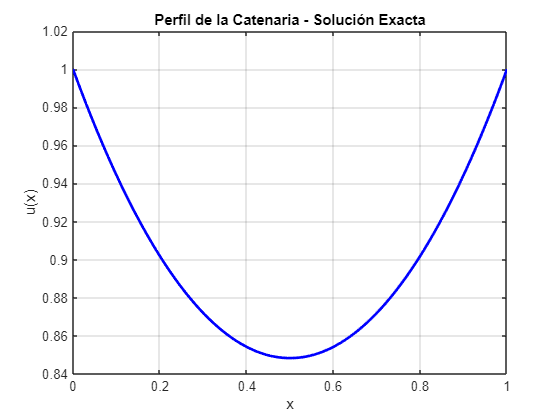


=== Método de Paso Fijo ===
Iteraciones Paso Fijo: 10000


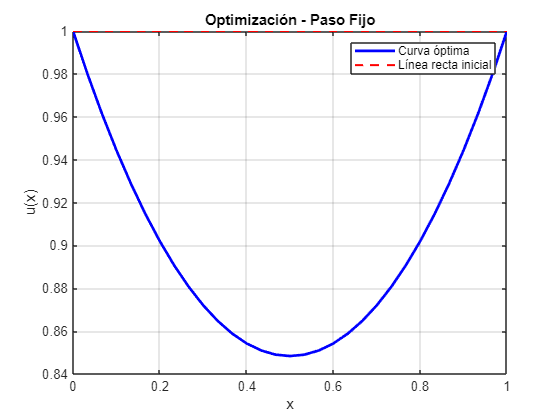


=== Método de Paso Variable ===
Iteraciones Paso Variable: 10000


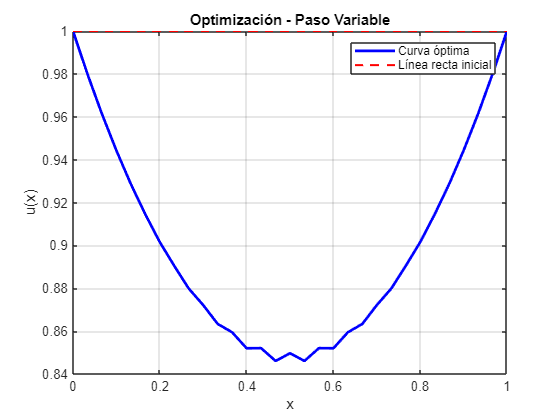

function practica2_opt()
    %% Configuración inicial
    clc;close all;

    % Parámetros generales
    n = 30;                      % Número de puntos
    tol = 1e-5;                  % Tolerancia
    max_iter = 10000;            % Máximo de iteraciones

    % Solución exacta
    fprintf('=== Solución Exacta ===\n');
    calcular_solucion_exacta();

    % Método de Paso Fijo
    fprintf('\n=== Método de Paso Fijo ===\n');
    t_fijo = 0.005;              % Tamaño de paso fijo
    [u_aprox_fijo, iter_fijo] = metodo_gradiente_paso_fijo(n, t_fijo, tol, max_iter);
    graficar_resultado(u_aprox_fijo, n, 'Paso Fijo');

    % Método de Paso Variable
    fprintf('\n=== Método de Paso Variable ===\n');
    [u_aprox_variable, iter_variable] = metodo_gradiente_paso_variable(n, tol, max_iter);
    graficar_resultado(u_aprox_variable, n, 'Paso Variable');
end

function calcular_solucion_exacta()
    % Parámetros de la catenaria
    a = 0.848338;
    b = 0.5;
    u_func = @(x) a * cosh((x - b) / a);
    x_range = linspace(0, 1, 100);

    % Graficar solución exacta
    figure;
    plot(x_range, u_func(x_range), 'LineWidth', 2, 'Color', 'b');
    grid on;
    title('Perfil de la Catenaria - Solución Exacta');
    xlabel('x');
    ylabel('u(x)');
end

function [u, iter] = metodo_gradiente_paso_fijo(n, t, tol, max_iter)
    % Inicialización
    u = ones(n + 1, 1); % Línea recta inicial
    grad = grad_F(u);
    iter = 0;

    % Iteraciones
    while norm(grad) > tol && iter < max_iter
        u_new = u - t * grad;
        u_new([1, end]) = 1;  % Condiciones de contorno
        grad = grad_F(u_new);
        u = u_new;
        iter = iter + 1;
    end

    fprintf('Iteraciones Paso Fijo: %d\n', iter);
end

function [u, iter] = metodo_gradiente_paso_variable(n, tol, max_iter)
    % Inicialización
    u = ones(n + 1, 1); % Línea recta inicial
    grad = grad_F(u);
    iter = 0;

    % Iteraciones
    while norm(grad) > tol && iter < max_iter
        f = @(t) F(u - t * grad);
        t_opt = buscar_t_optimo(f, 0, 1, tol);
        u_new = u - t_opt * grad;
        u_new([1, end]) = 1;  % Condiciones de contorno
        grad = grad_F(u_new);
        u = u_new;
        iter = iter + 1;
    end

    fprintf('Iteraciones Paso Variable: %d\n', iter);
end

function integral = F(u)
    n = length(u) - 1;
    integral = 0;
    for j = 1:n
        integral = integral + (u(j+1) + u(j)) * sqrt(1 + (n * (u(j+1) - u(j)))^2);
    end
    integral = integral / (2 * n);
end

function gradiente = grad_F(u)
    l = length(u);
    n = l - 1;
    c = 1 / (2 * n);
    gradiente = zeros(l, 1);

    % Gradiente en los puntos internos
    for j = 2:n
        gradiente(j) = (c + u(j) * n * (u(j) - u(j-1))) / sqrt(1 + (n * (u(j) - u(j-1)))^2) + ...
                       (c - u(j) * n * (u(j+1) - u(j))) / sqrt(1 + (n * (u(j+1) - u(j)))^2);
    end

    % Gradiente en los extremos
    gradiente(1) = (c - u(1) * n * (u(2) - u(1))) / sqrt(1 + (n * (u(2) - u(1)))^2);
    gradiente(l) = (c + u(l) * n * (u(l) - u(l-1))) / sqrt(1 + (n * (u(l) - u(l-1)))^2);
end

function t_opt = buscar_t_optimo(f, a, b, tol)
    phi = (1 + sqrt(5)) / 2; % Razón áurea
    c = b - (b - a) / phi;
    d = a + (b - a) / phi;

    while (b - a) > tol
        if f(c) < f(d)
            b = d;
        else
            a = c;
        end
        c = b - (b - a) / phi;
        d = a + (b - a) / phi;
    end

    t_opt = (a + b) / 2;
end

function graficar_resultado(u, n, metodo)
    x = linspace(0, 1, length(u));
    figure;
    plot(x, u, 'LineWidth', 2, 'Color', 'b');
    hold on;
    % Graficar línea recta inicial para referencia
    plot(x, ones(size(x)), 'r--', 'LineWidth', 1.5);
    grid on;
    title(sprintf('Optimización - %s', metodo));
    xlabel('x');
    ylabel('u(x)');
    legend('Curva óptima', 'Línea recta inicial');
end

practica2_opt()